# Rolling Statistics

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

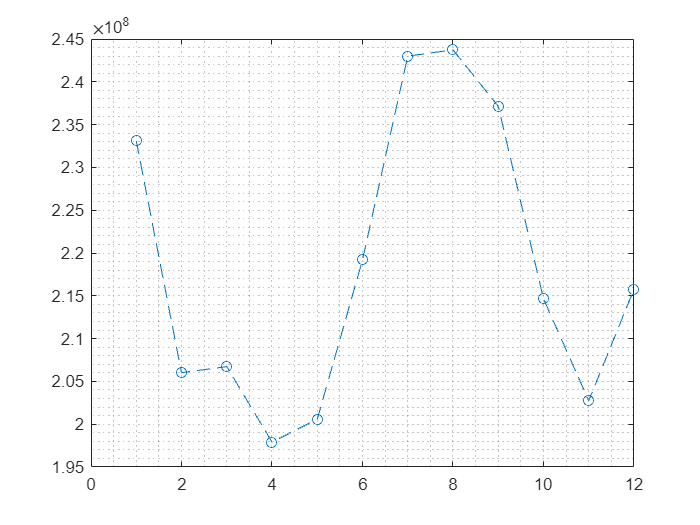

com = readmatrix("./data/electricity.xlsx", Sheet='com');
res = readmatrix("./data/electricity.xlsx", Sheet='res');
ind = readmatrix("./data/electricity.xlsx", Sheet='ind');
price = readmatrix("./data/electricity.xlsx", Sheet='price');

usage = ind + res + com;
firstYear = usage(:, 1);
plot(firstYear, "o--")
grid minor

price = price * 1000 / 100;
revenue = price .* usage;

## Task 1

The electricity usage for 1990 has been extracted and saved to the vector, `firstYear`.  To calculate the difference between elements of a  vector, use the `diff` function.

`diff``(``v``)`

diff1990 = diff(firstYear)

diff1990 =    -27089913
      706744
    -8814233
     2671160
    18604627
    23814548
      728633
    -6581330
   -22494591
   -11907913


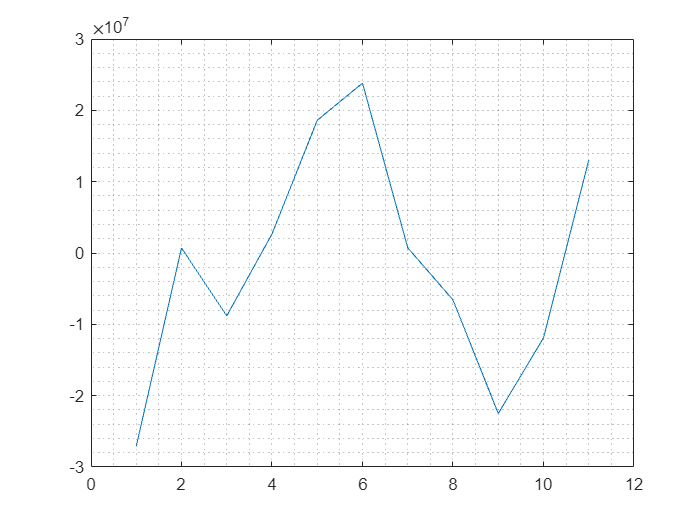

plot(diff1990)
grid minor

## Task 2

The largest increase in electricity usage is in June.  Is this true for the other years?  If there is regularly a sharp increase in July, that makes planning for high demand easier.

The `diff` function also works on matrices column-wise, meaning it calculates the difference vector of each column.  The output is a matrix with one fewer row.

diffByMonth = diff(usage)

diffByMonth =    -27089913   -21564248   -12324251         NaN   -20738386   -15926028   -15871738   -24135542   -20913298   -32276376         NaN         NaN   -26957162   -21965520   -21416474   -29476950   -23785401         NaN   -21085653         NaN   -33391382   -37138444   -23971689   -29193000         NaN   -22920000   -24070000   -42365000         NaN   -32462000
      706744    -5004508    -6269172         NaN    -7144499    -2692791    -6904992    -7077514     3908636     9295488         NaN    -3202402     3721237    -7793543    -8203433     7165024     8903214    -9695087         NaN    -2450300    -5917480    -4878471    -3219403     5762000    -6504000    -1390000   -10951000    15656000         NaN     5860000
    -8814233    -7965580    -7898242         NaN   -11334317   -14196528         NaN    -8717569   -13830352   -13686546   -12948632   -14622963    -9547739   -17708760   -15327660         NaN   -21713019   -16222747         NaN   -18280201   -25403238   -16813152

## Task 3

The plot command also works on matrices column-wise.  There will be a line plot for each column in the matrix.   For example, if `M` is 5-by-3, there will be three line plots on the graph.

`plot``(``M``)`

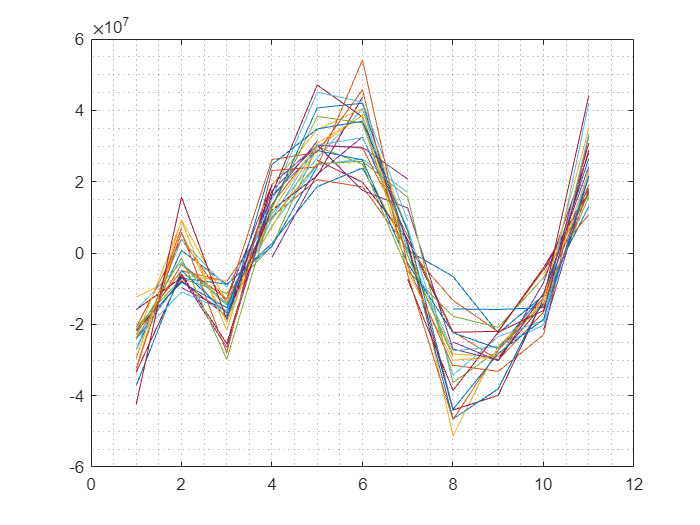

plot(diffByMonth)
grid minor

## Task 4

It looks like in the plot that the highest increases are in early summer and December.  

As you saw in the last practice, statistical functions work column-wise on matrices by default.  The output is a row vector with that statistic calculated for each column.

For the `max` and `min` functions, you can request a second output that gives you the index for the maximum of each column.

[maxDiffMonths, idxM] = max(diffByMonth)

maxDiffMonths =     23814548    20552790    25371177    32567112    29863339    26348047    25985009    24203462    30206807    38637143    30244449    25704818    40343247    43736208    28723791    45521636    40528884    30152758    30530220    42037612    47111597    41976937    45771030    38487000    31401000    38301000    45113000    28805000    36939000    54149000


idxM =      6     5     6     6     5     6     5     5     5     6     5     6     6     6     5     5     6     5    11    11     5     6     6     6     5     5     5    11     6     6


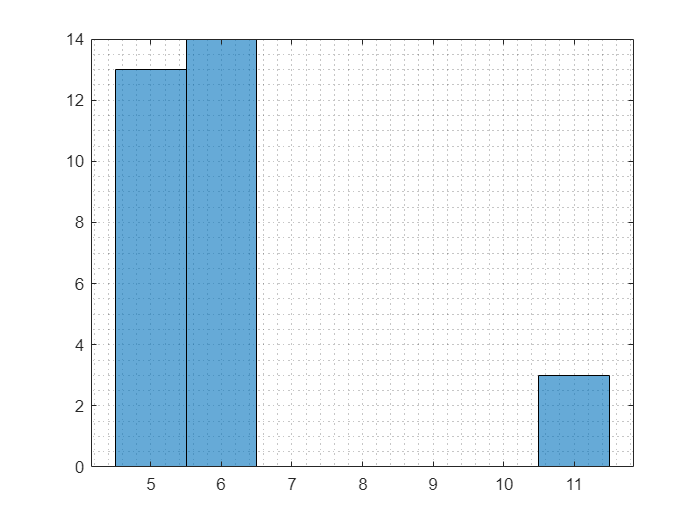

histogram(idxM)
grid minor

## Task 5

The `cumsum` function calculates the sum of an element with all the previous elements of a vector.  If the input is a matrix, the sums are calculated by column, and the output is a matrix of the same size.

`cumsum``(``M``)`

revCum = cumsum(revenue)

revCum = 1.0e+11 *

    0.1671    0.1729    0.1778    0.1821    0.1947    0.1942    0.2047    0.2098    0.2065    0.2086    0.2137       NaN    0.2279    0.2430    0.2531    0.2620    0.2904       NaN    0.3301       NaN    0.3474    0.3625    0.3540    0.3667       NaN    0.3980    0.3840    0.3878    0.4200    0.4030
    0.3212    0.3341    0.3479       NaN    0.3759    0.3796    0.3984    0.4034    0.3991    0.4011       NaN       NaN    0.4372    0.4689    0.4911    0.5056    0.5653       NaN    0.6394       NaN    0.6717    0.6901    0.6835    0.7048       NaN    0.7740    0.7435    0.7396       NaN    0.7727
    0.4777    0.4952    0.5180       NaN    0.5568    0.5658    0.5933    0.5975    0.5956    0.6005       NaN       NaN    0.6490    0.6976    0.7302    0.7588    0.8508       NaN       NaN       NaN    0.9958    1.0259    1.0146    1.0492       NaN    1.1498    1.1018    1.1144       NaN    1.1536
    0.6300    0.6539    0.6822       NaN    0.7331    0.7462       NaN    0.7

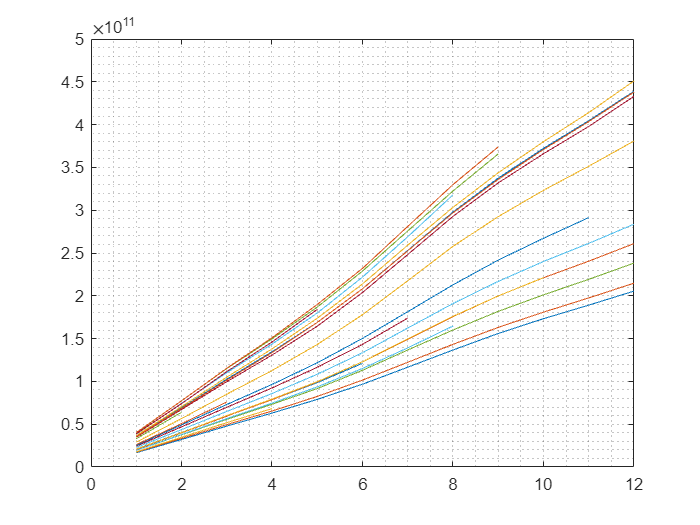

plot(revCum)
grid minor